**ESERCITAZIONE 1 - PARTE 2**

In questa esercitazione andiamo a vedere come impostare una semplice generica pipeline di Machine Learning.

Partiamo da un dataset artificiale ed finiamo con la misura delle performance, senza entrare in merito al tipo di classificatore che utilizziamo (utilizziamo infatto un classificatore fittizio, che prende decisioni quasi banali).

Procediemo nel seguente modo:

**1)** Generiamo un dataset di N misure di 3 fenomeni aleatori, di cui osserviamo 3 parametri distinti, ottenendo quindi una matrice Nx(M + 1) [vedere Parte 1].

% Fenomeno 1
mu_1 = [8 15 9]

mu_1 =      8    15     9


sigma_1 = 8*[1     0.5   0.3
             0.5   1     0
             0.3   0     1];

% Fenomeno 2
mu_2 = [12 9 11]

mu_2 =     12     9    11


sigma_2 = 12*[1     0     0.2
              0     1     0.6
              0.2   0.6   1];

% Fenomeno 3
mu_3 = [6 3 15]

mu_3 =      6     3    15


sigma_3 = 15*[1 0 0
              0 1 0
              0 0 1];

% Acquisizione del dataset
Nobs = 300;     % Numero di osservazioni che facciamo

dataset = [];
for i = 1:Nobs
    scelta = rand;       % "scelta" indica la casualità della scelta del fenomeno che si manifesta
    if scelta <= 0.2
        obs = mvnrnd(mu_1, sigma_1);    % "mvnrnd()" genera un valore casuale suguendo una Normale Multivariata con specifica media e matrice di covarianza
        c = 1;      % "c" indica la classe di appartenenza del fenomeno
    elseif scelta <= 0.9
        obs = mvnrnd(mu_2, sigma_2);
        c = 2;
    else
        obs = mvnrnd(mu_3, sigma_3);
        c = 3;
    end
    
    dataset = cat(1, dataset, [obs c]);     % scrivo l'osservazione nel dataset: le feature misurate e l'etichetta del fenomeno associato
end
dataset

dataset =     4.1580   11.3350    8.1335    1.0000
   13.0439    3.2504    7.2861    2.0000
    8.9059    6.3946   12.6305    3.0000
   10.1056   15.1318    8.7880    1.0000
   11.5136    4.0316   10.9170    2.0000
    3.6869    9.4599    8.9767    2.0000
   14.0476    7.6538    7.8696    2.0000
    9.5130    1.3870    2.9000    2.0000
    6.9840   17.5465   15.0370    2.0000
   13.8462   11.8209   15.7020    2.0000


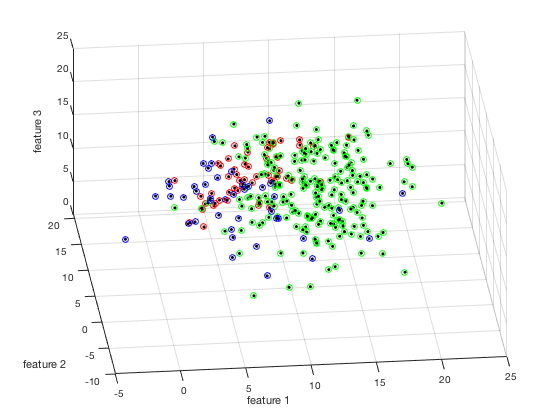


% Plot delle osservazioni nello spazio delle feature
cla
scatter3(dataset(:, 1), dataset(:, 2), dataset(:, 3), 'k.')     % disegno tutte le osservazioni alle coordinate delle relative feature
hold on

class_1_map = dataset(:, end) == 1;     % seleziono le osservazioni del fenomeno 1
scatter3(dataset(class_1_map, 1), dataset(class_1_map, 2), dataset(class_1_map, 3), 'ro')       % evidenzio le osservazioni selezionate di rosso

class_2_map = dataset(:, end) == 2;
scatter3(dataset(class_2_map, 1), dataset(class_2_map, 2), dataset(class_2_map, 3), 'go')

class_3_map = dataset(:, end) == 3;
scatter3(dataset(class_3_map, 1), dataset(class_3_map, 2), dataset(class_3_map, 3), 'bo')

xlabel('feature 1')     % scrivo il nome delle feature sugli assi
ylabel('feature 2')
zlabel('feature 3')

**2)** Per inizializzare il codice, dal dataset:

- estrarre la sotto-matrice delle feature;

- estrarre il sotto-vettore delle label;

- calcolare il numero di osservazioni totali;

- calcolare numero di classi distinte che abbiamo.

% Inizializzazione
features = dataset(:, 1:end - 1)   % tutto il dataset tranne l'ultima colonna

features =     4.1580   11.3350    8.1335
   13.0439    3.2504    7.2861
    8.9059    6.3946   12.6305
   10.1056   15.1318    8.7880
   11.5136    4.0316   10.9170
    3.6869    9.4599    8.9767
   14.0476    7.6538    7.8696
    9.5130    1.3870    2.9000
    6.9840   17.5465   15.0370
   13.8462   11.8209   15.7020


labels =      1
     2
     3
     1
     2
     2
     2
     2
     2
     2


Nobs = 300

Nclasses = 3

labels = dataset(:, end)       % solo l'ultima colonna
Nobs = length(labels)      % numero di righe del dataset
Nclasses = length(unique(labels))      % numero di etichette prese senza doppioni

**3)** Ora dobbiamo sviluppare il contenuto principale della pipeline ed utilizzare quindi il dataset che abbiamo per stimare le prestazioni di un classificatore scelto.

Avendo un numero di osservaioni limitato, conviene sempre dividere il dataset in:

- Training set: porzione di osservazioni sulle quali addestrare il classificatore;

- Test set: porzione di osservazioni (generalmente in numero inferiore rispetto a quella del training set) sulle quali testare la bravura del classificatore addestrato, chiedendogli di predire le etichette delle relative osservazioni (le etichette dei campioni di test, nascoste al classificatore, verranno utilizzate dopo per misrare il risultato).

*N.B.: Per il training e la classificazione utilizzare le funzioni "addestra_classificatore()" e "classifica_osservazioni()". Maggiori dettagli su queste funzioni saranno disponibili nelle prossime lezioni, quando affronteremo i differenti classificatori.*

Procedere provando ad implementare i seguenti metodi di validazione con classificazione e costruzione della Confusion Matrix:

- Hold Out Validation:

% === metodo: Hold Out Validation ===
train_percent = 0.8;
Ntrain_obs = round(train_percent*Nobs);

% Randomizza l'ordine delle osservazioni
randomize_map = randperm(Nobs);
features = features(randomize_map, :);
labels = labels(randomize_map);

% Dividi osservazioni in training set e test set
features_tr = features(1:Ntrain_obs, :);
labels_tr = labels(1:Ntrain_obs);
features_te = features(Ntrain_obs + 1:end, :);
labels_te = labels(Ntrain_obs + 1:end);

% Addestra il classificatore con il training set
parametri = addestra_classificatore(features_tr, labels_tr);

% Classifica le osservazioni del test set
label_predette = classifica_osservazioni(features_te, parametri);

% Per ogni osservazione del test set aggiungi +1 nella confusion matrix alla riga della classe reale e colonna della classe predetta
CM = zeros(Nclasses);
for i = 1:length(labels_te)
    CM(labels_te(i), label_predette(i)) = CM(labels_te(i), label_predette(i)) + 1;
end
% ===================================
CM

CM =     12     3     0
     4    32     2
     0     1     6


- K-fold Cross Validation

% === metodo: K-fold Cross Validation ===
Nfolds = 10;

% Costruisci gli indici delle fold
obs_per_fold = [];
for i = Nfolds:-1:1
    obs_per_fold = cat(2, obs_per_fold, ceil((Nobs - sum(obs_per_fold))/i));
end

fold_idx = [];
for i = 1:length(obs_per_fold)
    fold_idx = cat(1, fold_idx, repmat(i, [obs_per_fold(i) 1]));
end
fold_idx = fold_idx(randperm(Nobs));

CM = zeros(Nclasses);
for i = 1:Nfolds
    
    % Dividi osservazioni della fold in training set e test set
    features_te = features(fold_idx == i, :);
    labels_te = labels(fold_idx == i);
    features_tr = features(fold_idx ~= i, :);
    labels_tr = labels(fold_idx ~= i);
    
    % Addestra il classificatore con il training set e classifica le osservazioni del test set
    parametri = addestra_classificatore(features_tr, labels_tr);
    label_predette = classifica_osservazioni(features_te, parametri);
    
    % Per ogni osservazione della fold di test aggiungi +1 nella confusion matrix alla riga della classe reale e colonna della classe predetta
    for j = 1:length(labels_te)
        CM(labels_te(j), label_predette(j)) = CM(labels_te(j), label_predette(j)) + 1;
    end
end
% =======================================
CM

- Stratified K-fold Cross Validation *(difficile)*

% === metodo: Stratified K-fold Cross Validation ===
Nfolds = 10;

CM =     46     4     1
    18   179     9
     2     4    37



% Raggruppa le osservazioni per classe
obs_per_class = {};
for i = 1:Nclasses
    obs_per_class = cat(1, obs_per_class, {find(labels == i)});
end

% Costruisci gli indici delle fold per ogni raggruppamento
fold_idx_per_class = {};
for i = 1:Nclasses
    class_i_pos = obs_per_class{i};
    Nobs_class_i = length(class_i_pos);
    
    obs_per_fold = [];
    for j = Nfolds:-1:1
        obs_per_fold = cat(2, obs_per_fold, ceil((Nobs_class_i - sum(obs_per_fold))/j));
    end

    fold_class_i_idx = [];
    for j = 1:length(obs_per_fold)
        fold_class_i_idx = cat(1, fold_class_i_idx, repmat(j, [obs_per_fold(j) 1]));
    end
    fold_idx_per_class = cat(1, fold_idx_per_class, {fold_class_i_idx});
end

% Costruisci gli indici delle fold
fold_idx = cat(2, cell2mat(obs_per_class), cell2mat(fold_idx_per_class));
fold_idx = sortrows(fold_idx, 1);
fold_idx = fold_idx(:, 2);

CM = zeros(Nclasses);
for i = 1:Nfolds
    
    % Dividi osservazioni della fold in training set e test set
    features_te = features(fold_idx == i, :);
    labels_te = labels(fold_idx == i);
    features_tr = features(fold_idx ~= i, :);
    labels_tr = labels(fold_idx ~= i);
    
    % Addestra il classificatore con il training set e classifica le osservazioni del test set
    parametri = addestra_classificatore(features_tr, labels_tr);
    label_predette = classifica_osservazioni(features_te, parametri);
    
    % Per ogni osservazione della fold di test aggiungi +1 nella confusion matrix alla riga della classe reale e colonna della classe predetta
    for j = 1:length(labels_te)
        CM(labels_te(j), label_predette(j)) = CM(labels_te(j), label_predette(j)) + 1;
    end
end
% ==================================================
CM

- Leave-One-Out Cross Validation

% === Leave-One-Out Cross Validation ===
all_idx = 1:Nobs;

CM =     46     4     1
    17   179    10
     2     4    37


CM = zeros(Nclasses);
for i = 1:Nobs
    
    % Dividi le osservazioni della fold in training set e test
    features_te = features(i, :);
    labels_te = labels(i);
    features_tr = features(all_idx ~= i, :);
    labels_tr = labels(all_idx ~= i);
    
    % Addestra il classificatore con il training set e classifica l'osservazione di test
    parametri = addestra_classificatore(features_tr, labels_tr);
    label_predetta = classifica_osservazioni(features_te, parametri);
    
    % Per l'osservazione della fold di test aggiungi +1 nella confusion matrix alla riga della classe reale e colonna della classe predetta
    CM(labels_te, label_predetta) = CM(labels_te, label_predetta) + 1;
end
% ======================================
CM

- Bootstrap K-fold Cross Validation

% === metodo: Bootstrap K-fold Cross Validation ===
Nfolds = 10;

CM =     46     4     1
    20   177     9
     2     4    37


Nobs_per_fold = Nobs;

all_idx = 1:Nobs;
CM = zeros(Nclasses);
i = 1;
while i <= Nfolds

    % Costruisci gli indici delle fold
    tr_pos = randi([1 Nobs], [1 Nobs]);
    te_pos = setdiff(all_idx, tr_pos);
    
    if isempty(te_pos)
        continue
    end
    
    % Dividi le osservazioni della fold in training set e test
    features_tr = features(tr_pos, :);
    labels_tr = labels(tr_pos);
    features_te = features(te_pos, :);
    labels_te = labels(te_pos);
    
    % Addestra il classificatore con il training set e classifica le osservazioni del test set
    parametri = addestra_classificatore(features_tr, labels_tr);
    label_predette = classifica_osservazioni(features_te, parametri);
    
    % Per ogni osservazione della fold di test aggiungi +1 nella confusion matrix alla riga della classe reale e colonna della classe predetta
    for j = 1:length(labels_te)
        CM(labels_te(j), label_predette(j)) = CM(labels_te(j), label_predette(j)) + 1;
    end
    
    i = i + 1;
end
% =================================================
CM

*N.B.: i metodi di Nested Cross Validation verranno affrontati più avanti, quando utilizzeremo dei classificatori più complessi di quello utilizzato questa esercitazione, i quali presenteranno dei parametri da ottimizzare, potendo quindi impiegare anche l'utilizzo di un validation set.*

**4)** Per terminare la pipeline dobbiamo misurare le performance del nostro classificatore, calcolando le metriche generali dalla Confusion Matrix costruita in fase di test.

*N.B.: modoficare i parametri delle distribuzioni Normali che generano i dati per testare ogni singolo metodo, mantenendo commentati gli altri.*

Le metriche globali di:

- Accuratezza;

Provare a calcolare le metriche per classe di:

- Precision;

- Recall;

- F-score;

- G-score.

- Precision media;

- Recall media;

- F-score media;

- G-score media.

Le stesse metriche globali con media pesata secondo lo sbilanciamento del dataset (predominanza di campioni di una classe rispetto ad un'altra).

% Calcolo delle performance per classe
precision = diag(CM)./sum(CM, 2)

CM =    171    17     3
    77   672    29
     9    22   127


recall = diag(CM)'./sum(CM, 1)
f_score = 2*precision'.*recall./(precision' + recall)
g_score = sqrt(precision'.*recall)

% Calcolo delle performance globali
accuratezza = sum(diag(CM))/sum(CM(:))
precision_media = mean(precision)
recall_media = mean(recall)
f_score_media = mean(f_score)
g_score_media = mean(g_score)

% Calcolo delle performance globali pesate
sbilanciamento_classi = sum(CM, 1)/sum(CM(:))


precision =     0.8953
    0.8638
    0.8038


precision_media_pesata = sum(sbilanciamento_classi.*precision')

recall =     0.6654    0.9451    0.7987


recall_media_pesata = sum(sbilanciamento_classi.*recall)

f_score =     0.7634    0.9026    0.8013


f_score_media_pesata = sum(sbilanciamento_classi.*f_score)

g_score =     0.7718    0.9035    0.8013


g_score_media_pesata = sum(sbilanciamento_classi.*g_score)

accuratezza = 0.8607

precision_media = 0.8543

recall_media = 0.8031

f_score_media = 0.8224

g_score_media = 0.8255

sbilanciamento_classi =     0.2280    0.6309    0.1411


precision_media_pesata = 0.8625

recall_media_pesata = 0.8607

f_score_media_pesata = 0.8566

g_score_media_pesata = 0.8591